## Función con la dinámica del robot

function dxdt = RobotDynamics3dof(t, x, g, params, tau)

    m11 = cos(x(2))^2*params(1) + cos(x(2))*cos(x(2) + x(3))*params(2) + sin(x(2) + x(3))*params(3);
    m22 = params(1) + 2*cos(x(3))*params(2) + params(3);
    m23 = cos(x(3)) * params(2) + params(3);
    m32 = cos(x(3)) * params(2) + params(3);
    m33 = params(3);

    M = [m11 0   0;
        0   m22 m23;
        0   m32 m33];

    c11 = -cos(x(2))*sin(x(2))*x(5)*params(1) - 1/2*(cos(x(2))*sin(x(2) + x(3))*(x(5) + x(6)) + sin(x(2))*cos(x(2) + x(3))*x(5))*params(2) + cos(x(2) + x(3))*sin(x(2) + x(3))*(x(5) + x(6))*params(3);
    c12 = -cos(x(2))*sin(x(2))*x(4)*params(1) - 1/2*(sin(x(2))*cos(x(2) + x(3)) + cos(x(2))*sin(x(2) + x(3)))*x(4)*params(2) + sin(x(2) + x(3))*cos(x(2) + x(3))*x(4)*params(3);
    c13 = -1/2*cos(x(2))*sin(x(2) + x(3))*x(4)*params(2) + cos(x(2) + x(3))*sin(x(2) + x(3))*x(4)*params(3);
    c21 = cos(x(2))*sin(x(2))*x(4)*params(1) + 1/2*(sin(x(2))*cos(x(2) + x(3)) + cos(x(2))*sin(x(2) + x(3)))*x(4)*params(2) - sin(x(2) + x(3))*cos(x(2) + x(3))*x(4)*params(3);
    c22 = -sin(x(3))*x(6)*params(2);
    c23 = -sin(x(3))*(x(5) + x(6))*params(2);
    c31 = 1/2*cos(x(2))*sin(x(2) + x(3))*x(4)*params(2) - cos(x(2) + x(3))*sin(x(2) + x(3))*x(4)*params(3);
    c32 = sin(x(5))*params(2);
    c33 = 0;

    C = [c11 c12 c13;
         c21 c22 c23;
         c31 c32 c33];

    d1=params(4)*x(4);
    d2=params(5)*x(5);
    d3=params(6)*x(6);

    D=[d1; d2; d3];

    g2 = g*(cos(x(2))*params(7) + cos(x(2) + x(3))*params(8));
    g3 = g*cos(x(2) + x(3))*params(8);

    g = [0;
        g2;
        g3];
    
    q_dot = [x(4); x(5); x(6)];

    q_ddot = M \ (tau - C * q_dot - D - g);

    dxdt = [q_dot;
        q_ddot];

    disp(t)
end

## Control

a0 = [0; 0; 0; 0; 0; 0];
a3 = [0; 0; 0; 0; 0; 0];
a4 = [0; 0; 0; 0; 0; 0];
a5 = [0; 0; 0; 0; 0; 0];

tf = 5;

T = 0.01;

    % Parámetros PID
    Kp = [2.3, 2, 2.3]';
    Ki = [0.03, 0.03, 0.03]';
    Kd = [0.12, 0.12, 0.12]';

    xf = [50; 50; -40; 0; 0; 0];

pid = PID(Kp, Kd, Ki, T);


## Solución de la ecuación diferencial

format long

params = [  0.00349359
            0.00246677
            0.00333632
            0.00076823
            0.03526735
            0.00744473
            0.00449158
            0.01701218
          ];

x0 = [0; 45; -90; 0; 0; 0];

tspan = 0:T:5;
g = 9.81;

x = zeros(length(tspan), length(x0));  % Preasignar matriz de estado
x(1, :) = x0.'; 

%[t, x] = ode45(@(t,x) RobotDynamics3dof(t, x, g, params), tspan, x0);
for k = 1:length(tspan)-1
    [u, pid] = pid.compute(x(k,:)', xf);
    dxdt = RobotDynamics3dof(tspan(k), x(k,:)', g, params, u);
    x(k+1,:) = x(k,:) + T * dxdt';
end

     0

   0.010000000000000

   0.020000000000000

   0.030000000000000

   0.040000000000000

   0.050000000000000

   0.060000000000000

   0.070000000000000

   0.080000000000000

   0.090000000000000

   0.100000000000000



   0.110000000000000



   0.120000000000000



   0.130000000000000



   0.140000000000000



   0.150000000000000



   0.160000000000000



   0.170000000000000



   0.180000000000000



   0.190000000000000



   0.200000000000000



   0.210000000000000



   0.220000000000000



   0.230000000000000



   0.240000000000000



   0.250000000000000



   0.260000000000000



   0.270000000000000



   0.280000000000000



   0.290000000000000



   0.300000000000000



   0.310000000000000



   0.320000000000000



   0.330000000000000



   0.340000000000000



   0.350000000000000



   0.360000000000000



   0.370000000000000



   0.380000000000000



   0.390000000000000



   0.400000000000000



   0.410000000000000



   0.420000000000000



   0.430000000000000



   0.440000000000000



   0.450000000000000



   0.460000000000000



   0.470000000000000



   0.480000000000000



   0.490000000000000



   0.500000000000000



   0.510000000000000



   0.520000000000000



   0.530000000000000



   0.540000000000000



   0.550000000000000



   0.560000000000000



   0.570000000000000



   0.580000000000000



   0.590000000000000



   0.600000000000000



   0.610000000000000



   0.620000000000000



   0.630000000000000



   0.640000000000000



   0.650000000000000



   0.660000000000000



   0.670000000000000



   0.680000000000000



   0.690000000000000



   0.700000000000000



   0.710000000000000



   0.720000000000000



   0.730000000000000



   0.740000000000000



   0.750000000000000



   0.760000000000000



   0.770000000000000



   0.780000000000000



   0.790000000000000



   0.800000000000000



   0.810000000000000



   0.820000000000000



   0.830000000000000



   0.840000000000000



   0.850000000000000



   0.860000000000000



   0.870000000000000



   0.880000000000000



   0.890000000000000



   0.900000000000000



   0.910000000000000



   0.920000000000000



   0.930000000000000



   0.940000000000000



   0.950000000000000



   0.960000000000000



   0.970000000000000



   0.980000000000000



   0.990000000000000



     1



   1.010000000000000



   1.020000000000000



   1.030000000000000



   1.040000000000000



   1.050000000000000



   1.060000000000000



   1.070000000000000



   1.080000000000000



   1.090000000000000



   1.100000000000000



   1.110000000000000



   1.120000000000000



   1.130000000000000



   1.140000000000000



   1.150000000000000



   1.160000000000000



   1.170000000000000



   1.180000000000000



   1.190000000000000



   1.200000000000000



   1.210000000000000



   1.220000000000000



   1.230000000000000



   1.240000000000000



   1.250000000000000



   1.260000000000000



   1.270000000000000



   1.280000000000000



   1.290000000000000



   1.300000000000000



   1.310000000000000



   1.320000000000000



   1.330000000000000



   1.340000000000000



   1.350000000000000



   1.360000000000000



   1.370000000000000



   1.380000000000000



   1.390000000000000



   1.400000000000000



   1.410000000000000



   1.420000000000000



   1.430000000000000



   1.440000000000000



   1.450000000000000



   1.460000000000000



   1.470000000000000



   1.480000000000000



   1.490000000000000



   1.500000000000000



   1.510000000000000



   1.520000000000000



   1.530000000000000



   1.540000000000000



   1.550000000000000



   1.560000000000000



   1.570000000000000



   1.580000000000000



   1.590000000000000



   1.600000000000000



   1.610000000000000



   1.620000000000000



   1.630000000000000



   1.640000000000000



   1.650000000000000



   1.660000000000000



   1.670000000000000



   1.680000000000000



   1.690000000000000



   1.700000000000000



   1.710000000000000



   1.720000000000000



   1.730000000000000



   1.740000000000000



   1.750000000000000



   1.760000000000000



   1.770000000000000



   1.780000000000000



   1.790000000000000



   1.800000000000000



   1.810000000000000



   1.820000000000000



   1.830000000000000



   1.840000000000000



   1.850000000000000



   1.860000000000000



   1.870000000000000



   1.880000000000000



   1.890000000000000



   1.900000000000000



   1.910000000000000



   1.920000000000000



   1.930000000000000



   1.940000000000000



   1.950000000000000



   1.960000000000000



   1.970000000000000



   1.980000000000000



   1.990000000000000



     2



   2.010000000000000



   2.020000000000000



   2.030000000000000



   2.040000000000000



   2.050000000000000



   2.060000000000000



   2.070000000000000



   2.080000000000000



   2.090000000000000



   2.100000000000000



   2.110000000000000



   2.120000000000000



   2.130000000000000



   2.140000000000000



   2.150000000000000



   2.160000000000000



   2.170000000000000



   2.180000000000000



   2.190000000000000



   2.200000000000000



   2.210000000000000



   2.220000000000000



   2.230000000000000



   2.240000000000000



   2.250000000000000



   2.260000000000000



   2.270000000000000



   2.280000000000000



   2.290000000000000



   2.300000000000000



   2.310000000000000



   2.320000000000000



   2.330000000000000



   2.340000000000000



   2.350000000000000



   2.360000000000000



   2.370000000000000



   2.380000000000000



   2.390000000000000



   2.400000000000000



   2.410000000000000



   2.420000000000000



   2.430000000000000



   2.440000000000000



   2.450000000000000



   2.460000000000000



   2.470000000000000



   2.480000000000000



   2.490000000000000



   2.500000000000000



   2.510000000000000



   2.520000000000000



   2.530000000000000



   2.540000000000000



   2.550000000000000



   2.560000000000000



   2.570000000000000



   2.580000000000000



   2.590000000000000



   2.600000000000000



   2.610000000000000



   2.620000000000000



   2.630000000000000



   2.640000000000000



   2.650000000000000



   2.660000000000000



   2.670000000000000



   2.680000000000000



   2.690000000000000



   2.700000000000000



   2.710000000000000



   2.720000000000000



   2.730000000000000



   2.740000000000000



   2.750000000000000



   2.760000000000000



   2.770000000000000



   2.780000000000000



   2.790000000000000



   2.800000000000000



   2.810000000000000



   2.820000000000000



   2.830000000000000



   2.840000000000000



   2.850000000000000



   2.860000000000000



   2.870000000000000



   2.880000000000000



   2.890000000000000



   2.900000000000000



   2.910000000000000



   2.920000000000000



   2.930000000000000



   2.940000000000000



   2.950000000000000



   2.960000000000000



   2.970000000000000



   2.980000000000000



   2.990000000000000



     3



   3.010000000000000



   3.020000000000000



   3.030000000000000



   3.040000000000000



   3.050000000000000



   3.060000000000000



   3.070000000000000



   3.080000000000000



   3.090000000000000



   3.100000000000000



   3.110000000000000



   3.120000000000000



   3.130000000000000



   3.140000000000000



   3.150000000000000



   3.160000000000000



   3.170000000000000



   3.180000000000000



   3.190000000000000



   3.200000000000000



   3.210000000000000



   3.220000000000000



   3.230000000000000



   3.240000000000000



   3.250000000000000



   3.260000000000000



   3.270000000000000



   3.280000000000000



   3.290000000000000



   3.300000000000000



   3.310000000000000



   3.320000000000000



   3.330000000000000



   3.340000000000000



   3.350000000000000



   3.360000000000000



   3.370000000000000



   3.380000000000000



   3.390000000000000



   3.400000000000000



   3.410000000000000



   3.420000000000000



   3.430000000000000



   3.440000000000000



   3.450000000000000



   3.460000000000000



   3.470000000000000



   3.480000000000000



   3.490000000000000



   3.500000000000000



   3.510000000000000



   3.520000000000000



   3.530000000000000



   3.540000000000000



   3.550000000000000



   3.560000000000000



   3.570000000000000



   3.580000000000000



   3.590000000000000



   3.600000000000000



   3.610000000000000



   3.620000000000000



   3.630000000000000



   3.640000000000000



   3.650000000000000



   3.660000000000000



   3.670000000000000



   3.680000000000000



   3.690000000000000



   3.700000000000000



   3.710000000000000



   3.720000000000000



   3.730000000000000



   3.740000000000000



   3.750000000000000



   3.760000000000000



   3.770000000000000



   3.780000000000000



   3.790000000000000



   3.800000000000000



   3.810000000000000



   3.820000000000000



   3.830000000000000



   3.840000000000000



   3.850000000000000



   3.860000000000000



   3.870000000000000



   3.880000000000000



   3.890000000000000



   3.900000000000000



   3.910000000000000



   3.920000000000000



   3.930000000000000



   3.940000000000000



   3.950000000000000



   3.960000000000000



   3.970000000000000



   3.980000000000000



   3.990000000000000



     4



   4.010000000000000



   4.020000000000000



   4.030000000000000



   4.040000000000000



   4.050000000000000



   4.060000000000000



   4.070000000000000



   4.080000000000000



   4.090000000000000



   4.100000000000000



   4.110000000000000



   4.120000000000000



   4.130000000000000



   4.140000000000000



   4.150000000000000



   4.160000000000000



   4.170000000000000



   4.180000000000000



   4.190000000000000



   4.200000000000000



   4.210000000000000



   4.220000000000000



   4.230000000000000



   4.240000000000000



   4.250000000000000



   4.260000000000000



   4.270000000000000



   4.280000000000000



   4.290000000000000



   4.300000000000000



   4.310000000000000



   4.320000000000000



   4.330000000000000



   4.340000000000000



   4.350000000000000



   4.360000000000000



   4.370000000000000



   4.380000000000000



   4.390000000000000



   4.400000000000000



   4.410000000000000



   4.420000000000000



   4.430000000000000



   4.440000000000000



   4.450000000000000



   4.460000000000000



   4.470000000000000



   4.480000000000000



   4.490000000000000



   4.500000000000000



   4.510000000000000



   4.520000000000000



   4.530000000000000



   4.540000000000000



   4.550000000000000



   4.560000000000000



   4.570000000000000



   4.580000000000000



   4.590000000000000



   4.600000000000000



   4.610000000000000



   4.620000000000000



   4.630000000000000



   4.640000000000000



   4.650000000000000



   4.660000000000000



   4.670000000000000



   4.680000000000000



   4.690000000000000



   4.700000000000000



   4.710000000000000



   4.720000000000000



   4.730000000000000



   4.740000000000000



   4.750000000000000



   4.760000000000000



   4.770000000000000



   4.780000000000000



   4.790000000000000



   4.800000000000000



   4.810000000000000



   4.820000000000000



   4.830000000000000



   4.840000000000000



   4.850000000000000



   4.860000000000000



   4.870000000000000



   4.880000000000000



   4.890000000000000



   4.900000000000000



   4.910000000000000



   4.920000000000000



   4.930000000000000



   4.940000000000000



   4.950000000000000



   4.960000000000000



   4.970000000000000



   4.980000000000000



   4.990000000000000



## Gráficas de articulaciones

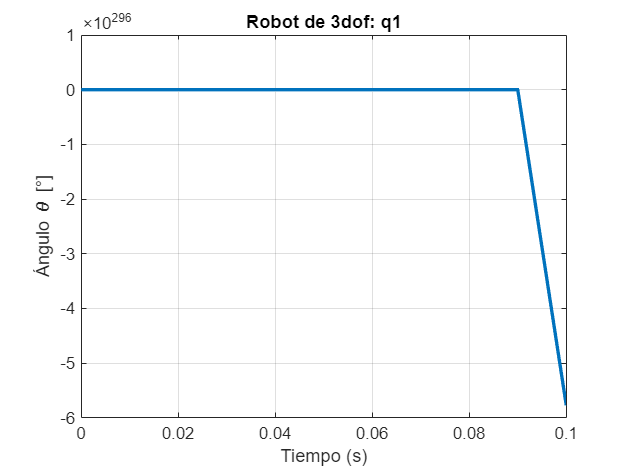

figure;
plot(tspan, x(:,1)*180/pi, 'LineWidth', 2);
xlabel('Tiempo (s)');
ylabel('Ángulo \theta [°]');
title('Robot de 3dof: q1');
grid on;

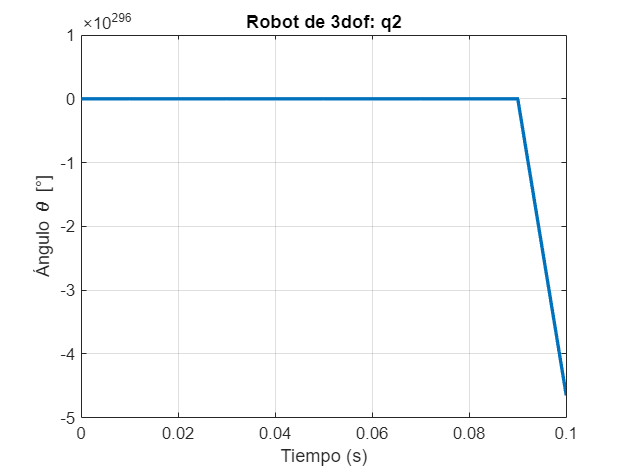


figure;
plot(tspan, x(:,2)*180/pi, 'LineWidth', 2);
xlabel('Tiempo (s)');
ylabel('Ángulo \theta [°]');
title('Robot de 3dof: q2');
grid on;

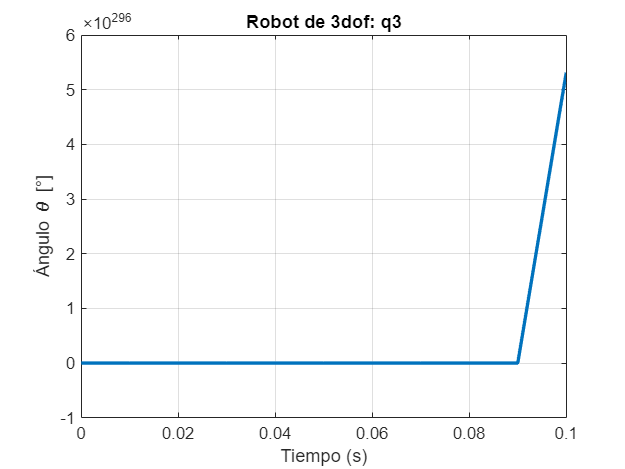


figure;
plot(tspan, x(:,3)*180/pi, 'LineWidth', 2);
xlabel('Tiempo (s)');
ylabel('Ángulo \theta [°]');
title('Robot de 3dof: q3');
grid on;

## Animación

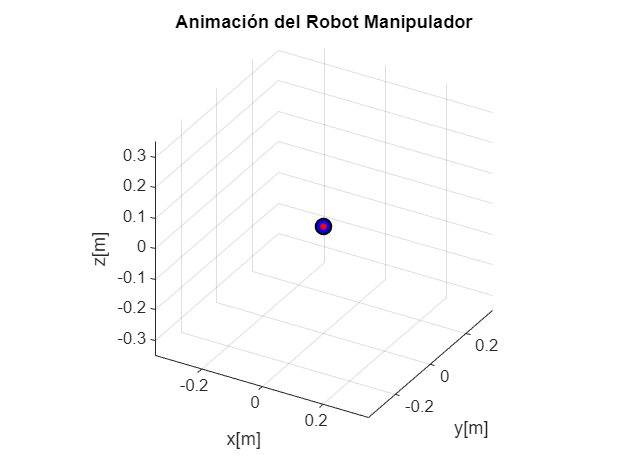

dh = ["q1", 0, 0,      pi/2; 
      "q2", 0, 0.145,  0   ; 
      "q3", 0, 0.1738, 0   ];

geomagic = Robot(3, dh);

animateRobot(tspan, x, 0.001, geomagic);